# Design the second order LADRC controller

## Prepare the plant

s = tf('s');
P = tf(16.454, conv([1, 0], conv([0.709, 1], [0.01, 1] )))

P =
 
             16.45
  ---------------------------
  0.00709 s^3 + 0.719 s^2 + s
 
Continuous-time transfer function.



## The Plant is unstable for open loop running

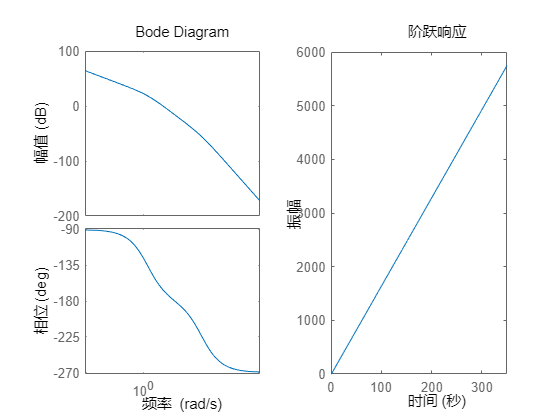

figure
subplot(1,2,1)
bode(P)
subplot(1,2,2)
step(P)

## crossover frequency wf=20 rad/s, phase margin PM=60° 

wf = 20;
PM = 60;

## Design the LADRC

Require phase compensate 67.276
gamma : 7.0672
wo : 141.3435
wc : 2.83
b0 : 58.3872
Design result: 
PM = 60.0002°
wf = 19.9995 rad/s
Feedback loop BW = 5.6483 Hz
System BW = 0.2953 Hz


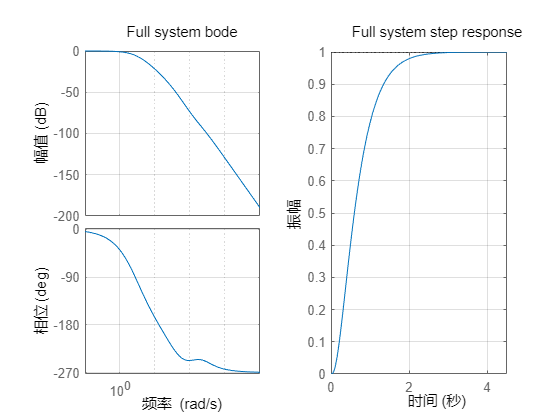

[wo, wc, b0] = DesignLADRC2(P, wf, PM);

## The controller get PM=60.0° and wf=20.0 rad/s. 

## The feedback loop BW = 5.65 Hz

## The close loop system's BW = 0.29 Hz 